# Simulate Simple Flight Scenario and Sensor in Unreal Engine Environment

UAV Toolbox™ provides blocks for visualizing sensors in a simulation environment that uses the Unreal Engine® from Epic Games®. This model simulates a simple flight scenario in a prebuilt scene and captures data from the scene using a fisheye camera sensor. Use this model to learn the basics of configuring and simulating scenes, vehicles, and sensors. For more background on the Unreal Engine simulation environment, see [Unreal Engine Simulation for Unmanned Aerial Vehicles](docid:uav_ug#mw_ffba8cdc-968b-46ac-a52a-9e832822583d).

## Model Overview

The model consists of these main components:

- Scene – A [Simulation 3D Scene Configuration](docid:uav_ref#mw_96a521fd-316f-497b-bc01-b2c5f4083563) block configures the scene in which you simulate.

- UAV – A [Simulation 3D UAV Vehicle](docid:uav_ref#mw_619937da-a01b-431e-88b5-4f39caf0b95a) blocks configures the quadrotor within the scene and specifies its trajectory.

- Sensor – A [Simulation 3D Fisheye Camera](docid:uav_ref#mw_788d6799-c9ab-4d19-a18a-cb3d6d4b5500) configures the mounting position and parameters of the fisheye camera used to capture simulation data. A [Video Viewer](docid:vision_ref#f225831) block visualizes the simulation output of this sensor.

You can open the model using the following command.

open_system("uav_ue4_depth.slx")

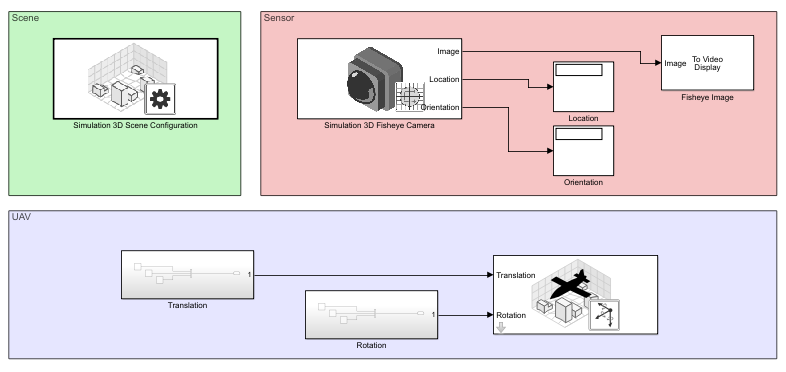

## Inspect Scene

In the Simulation 3D Scene Configuration block, the Scene name parameter determines the scene where the simulation takes place. This model uses the [US City Block](docid:uav_ref#mw_c39cc898-f165-40e0-b5bc-635e3b275057) scene. To explore a scene, you can open the 2D image corresponding to the Unreal Engine scene.

imshow('USCityBlock.jpg',...
    'XData', [-250, 210],...
    'YData', [-225, 235]);
set(gca,'YDir','reverse')

The Scene view parameter of this block determines the view from which the Unreal Engine window displays the scene. In this block, Scene view is set to the root of the scene (the scene origin), select root. You can also change the scene view to the quadrotor UAV.

## Inspect Vehicle

The Simulation 3D UAV Vehicle block models the quadcopter, named  `Quadrotor1`, in the scenario. During simulation, the quadrotor flies one complete circle with a radius of 5m and elevation of 1.5m around the center of the scene. The yaw angle of the quadrotor viewpoint oscillates from left to right in the direction of travel. To create more realistic trajectories, you can obtain waypoints from a scene and specify these waypoints as inputs to the Simulation 3D UAV Vehicle block.

## Inspect Sensor

The Simulation 3D Fisheye Camera block models the sensor used in the scenario. Open this block and inspect its parameters. 

- The **Mounting** tab contains parameters that determine the mounting location of the sensor. The fisheye camera sensor is mounted forward along the X-axis of the  center of the ego vehicle by 0.1 meters.

- The **Parameters** tab contains the intrinsic camera parameters of a fisheye camera. These parameters are set to their default values except the mapping coefficient, where the second coefficient is set to -0.0005 to model lens distortion.

- The **Ground Truth** tab contains a parameter for outputting the location and orientation of the sensor in meters and radians. In this model, the block outputs these values so you can see how they change during simulation. 

The block outputs images captured from the simulation. During simulation, the Video Viewer block displays these images. This image shows a sample snapshot from the Video Viewer block stream.

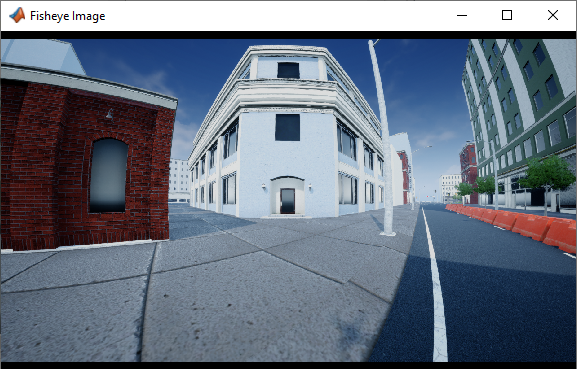

## Simulate Model

When the simulation begins, it can take a few seconds for the visualization engine to initialize, especially when you are running it for the first time. The `MathWorks_Aerospace` window shows a view of the scene in the Unreal Engine environment.

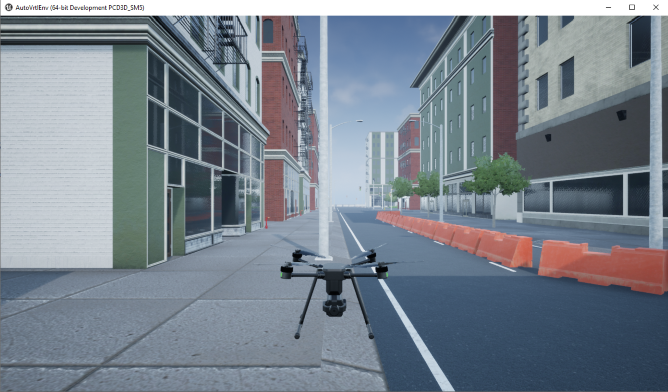

To change the view of the scene during simulation, use the numbers 1–9 on the numeric keypad. For a bird's-eye view of the scene, press 0.

After simulating the model, try modifying the intrinsic camera parameters and observe the effects on simulation. You can also change the type of sensor block. For example, try substituting the 3D Simulation Fisheye Camera with a 3D Simulation Camera block. For more details on the available sensor blocks, see [Choose a Sensor for Unreal Engine Simulation](docid:uav_ug#mw_49d2618c-2297-484b-832c-9f00147d09e6).

*Copyright 2020 The MathWorks, Inc.*

function [boxes,labels,scores] = tflite_predict(in)
persistent net;
if isempty(net)
    net = loadTFLiteModel('lite-model_yolo-v5-tflite_tflite_model_1.tflite');
end
 net.NumThreads=8;
 [boxes,labels,scores,~]= predict(net,in);
end